# CHURN PREDICTION MODEL

### Step 1: preprocessing, cleaning data, and descriptive statistics.

% Importing the data, text file format and encoding file specified.
opts = delimitedTextImportOptions("NumVariables", 14, "Encoding", "UTF-8");

Specifying the column names and variables types (within the original data, all the variables are of the same type).

opts.VariableNames = ["AnonymousCustomerID", "CallFailure", "Complains", "SubscriptionLength", "ChargeAmount", "SecondsOfUse", "FrequencyOfUse", "FrequencyOfSMS", "DistinctCalledNumbers", "AgeGroup", "TariffPlan", "Status", "Churn", "CustomerValue"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

Importing data

churn_data = readtable("Churn_Dataset.csv", opts);
churn_data = rmmissing(churn_data);

Calling variables and converting Complains, AgeGroup, TariffPlan, Status, and Churn into categorical vars (this is done for further plotting).

AnonymousCustomerID	  = churn_data.AnonymousCustomerID;
CallFailure	          = churn_data.CallFailure;
Complains             = categorical(churn_data.Complains); 	
SubscriptionLength    = churn_data.SubscriptionLength;	
ChargeAmount          = churn_data.ChargeAmount;	
SecondsofUse          = churn_data.SecondsOfUse;	
FrequencyofUse        = churn_data.FrequencyOfUse;	
FrequencyofSMS        = churn_data.FrequencyOfSMS;	
DistinctCalledNumbers = churn_data.DistinctCalledNumbers;	
AgeGroup              = categorical(churn_data.AgeGroup);	
TariffPlan            = categorical(churn_data.TariffPlan);	
Status                = categorical(churn_data.Status);	
Churn                 = categorical(churn_data.Churn);	
CustomerValue         = churn_data.CustomerValue;

Descriptive Statistics | continuous variables (except AnonymousCustomerID)

2) CallFailure

CallFailure_mean        = mean(CallFailure);
CallFailure_median      = median(CallFailure);
CallFailure_mode        = mode(CallFailure);
CallFailure_minimum     = min(CallFailure);
CallFailure_maximum     = max(CallFailure);
CallFailure_quartiles   = [0.25:0.25:1; quantile(CallFailure, 0.25:0.25:1)];


% Cell array for CallFailure stats
CallFailure_stats = {'Mean', CallFailure_mean; ...
         'Median', CallFailure_median; ...
         'Mode', CallFailure_mode; ...
         'Minimum', CallFailure_minimum; ...
         'Maximum', CallFailure_maximum; ...
         'Quartiles', CallFailure_quartiles}

CallFailure_stats = 6×2 cell array
    {'Mean'     }    {[  7.6279]}
    {'Median'   }    {[       6]}
    {'Mode'     }    {[       0]}
    {'Minimum'  }    {[       0]}
    {'Maximum'  }    {[      36]}
    {'Quartiles'}    {2×4 double}


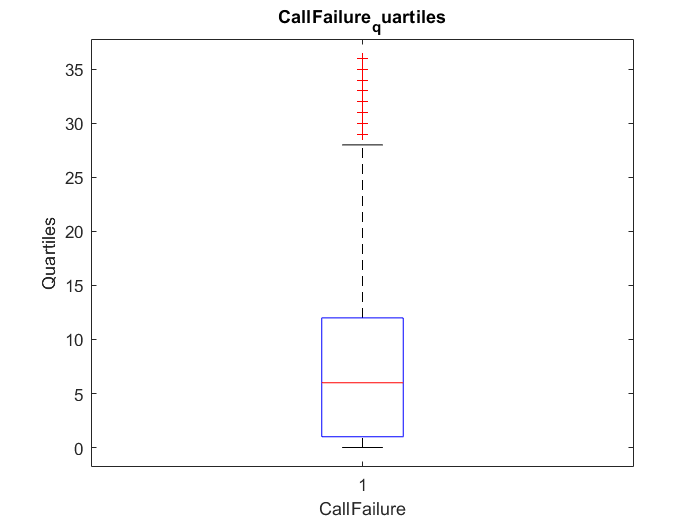


% Boxplot - CallFailure_quartiles
figure(1);
boxplot(CallFailure)
xlabel('CallFailure')
ylabel('Quartiles')
title('CallFailure_quartiles')

4) SubscriptionLength

SubscriptionLength_mean        = mean(SubscriptionLength);
SubscriptionLength_median      = median(SubscriptionLength);
SubscriptionLength_mode        = mode(SubscriptionLength);
SubscriptionLength_minimum     = min(SubscriptionLength);
SubscriptionLength_maximum     = max(SubscriptionLength);
SubscriptionLength_quartiles   = [0.25:0.25:1; quantile(SubscriptionLength, 0.25:0.25:1)];


% Cell array for SubscriptionLength stats
SubscriptionLength_stats = {'Mean', SubscriptionLength_mean; ...
         'Median', SubscriptionLength_median; ...
         'Mode', SubscriptionLength_mode; ...
         'Minimum', SubscriptionLength_minimum; ...
         'Maximum', SubscriptionLength_maximum; ...
         'Quartiles', SubscriptionLength_quartiles}

SubscriptionLength_stats = 6×2 cell array
    {'Mean'     }    {[ 32.5419]}
    {'Median'   }    {[      35]}
    {'Mode'     }    {[      36]}
    {'Minimum'  }    {[       3]}
    {'Maximum'  }    {[      47]}
    {'Quartiles'}    {2×4 double}


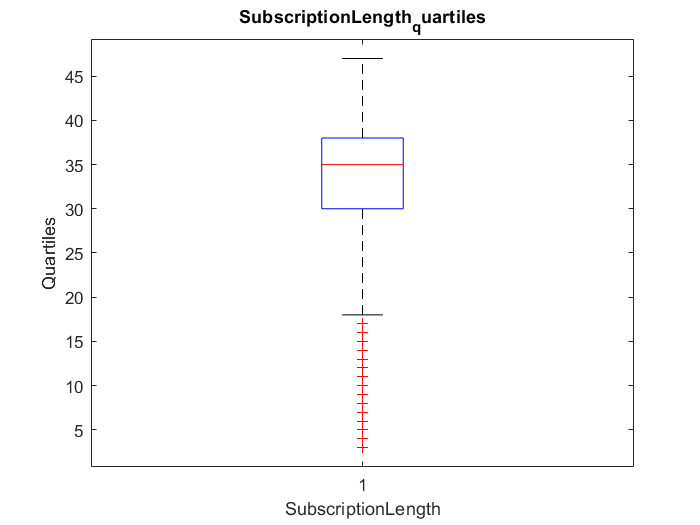


% Boxplot - SubscriptionLength_quartiles
figure(2);
boxplot(SubscriptionLength)
xlabel('SubscriptionLength')
ylabel('Quartiles')
title('SubscriptionLength_quartiles')

5) ChargeAmount

ChargeAmount_mean        = mean(ChargeAmount);
ChargeAmount_median      = median(ChargeAmount);
ChargeAmount_mode        = mode(ChargeAmount);
ChargeAmount_minimum     = min(ChargeAmount);
ChargeAmount_maximum     = max(ChargeAmount);
ChargeAmount_quartiles   = [0.25:0.25:1; quantile(ChargeAmount, 0.25:0.25:1)];


% Cell array for ChargeAmount stats
ChargeAmount_stats = {'Mean', ChargeAmount_mean; ...
         'Median', ChargeAmount_median; ...
         'Mode', ChargeAmount_mode; ...
         'Minimum', ChargeAmount_minimum; ...
         'Maximum', ChargeAmount_maximum; ...
         'Quartiles', ChargeAmount_quartiles}

ChargeAmount_stats = 6×2 cell array
    {'Mean'     }    {[  0.9429]}
    {'Median'   }    {[       0]}
    {'Mode'     }    {[       0]}
    {'Minimum'  }    {[       0]}
    {'Maximum'  }    {[      10]}
    {'Quartiles'}    {2×4 double}


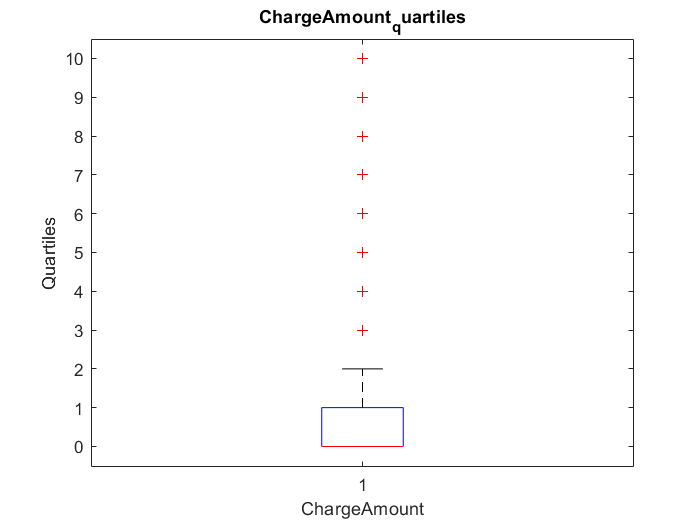


% Boxplot - ChargeAmount_quartiles
figure(3);
boxplot(ChargeAmount)
xlabel('ChargeAmount')
ylabel('Quartiles')
title('ChargeAmount_quartiles')

6) SecondsofUse

SecondsofUse_mean        = mean(SecondsofUse);
SecondsofUse_median      = median(SecondsofUse);
SecondsofUse_mode        = mode(SecondsofUse);
SecondsofUse_minimum     = min(SecondsofUse);
SecondsofUse_maximum     = max(SecondsofUse);
SecondsofUse_quartiles   = [0.25:0.25:1; quantile(SecondsofUse, 0.25:0.25:1)];


% Cell array for SecondsofUse stats
SecondsofUse_stats = {'Mean', SecondsofUse_mean; ...
         'Median', SecondsofUse_median; ...
         'Mode', SecondsofUse_mode; ...
         'Minimum', SecondsofUse_minimum; ...
         'Maximum', SecondsofUse_maximum; ...
         'Quartiles', SecondsofUse_quartiles}

SecondsofUse_stats = 6×2 cell array
    {'Mean'     }    {[4.4725e+03]}
    {'Median'   }    {[      2990]}
    {'Mode'     }    {[         0]}
    {'Minimum'  }    {[         0]}
    {'Maximum'  }    {[     17090]}
    {'Quartiles'}    {2×4 double  }


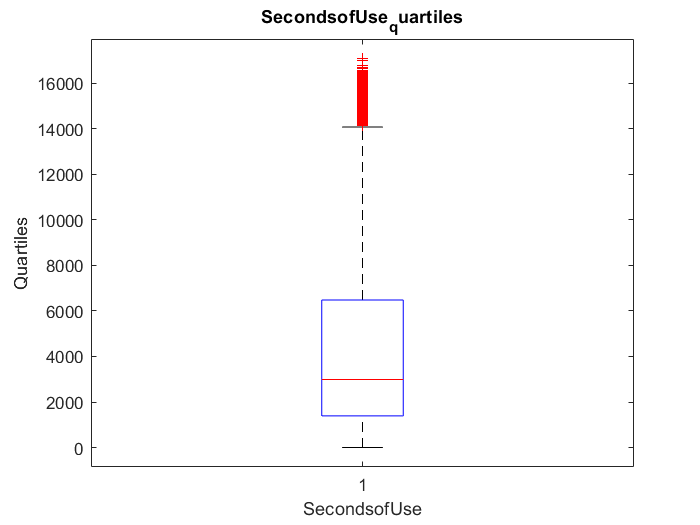


% Boxplot - SecondsofUse_quartiles
figure(4);
boxplot(SecondsofUse)
xlabel('SecondsofUse')
ylabel('Quartiles')
title('SecondsofUse_quartiles')

7) FrequencyofUse

FrequencyofUse_mean        = mean(FrequencyofUse);
FrequencyofUse_median      = median(FrequencyofUse);
FrequencyofUse_mode        = mode(FrequencyofUse);
FrequencyofUse_minimum     = min(FrequencyofUse);
FrequencyofUse_maximum     = max(FrequencyofUse);
FrequencyofUse_quartiles   = [0.25:0.25:1; quantile(FrequencyofUse, 0.25:0.25:1)];


% Cell array for FrequencyofUse stats
FrequencyofUse_stats = {'Mean', FrequencyofUse_mean; ...
         'Median', FrequencyofUse_median; ...
         'Mode', FrequencyofUse_mode; ...
         'Minimum', FrequencyofUse_minimum; ...
         'Maximum', FrequencyofUse_maximum; ...
         'Quartiles', FrequencyofUse_quartiles}

FrequencyofUse_stats = 6×2 cell array
    {'Mean'     }    {[ 69.4606]}
    {'Median'   }    {[      54]}
    {'Mode'     }    {[       0]}
    {'Minimum'  }    {[       0]}
    {'Maximum'  }    {[     255]}
    {'Quartiles'}    {2×4 double}


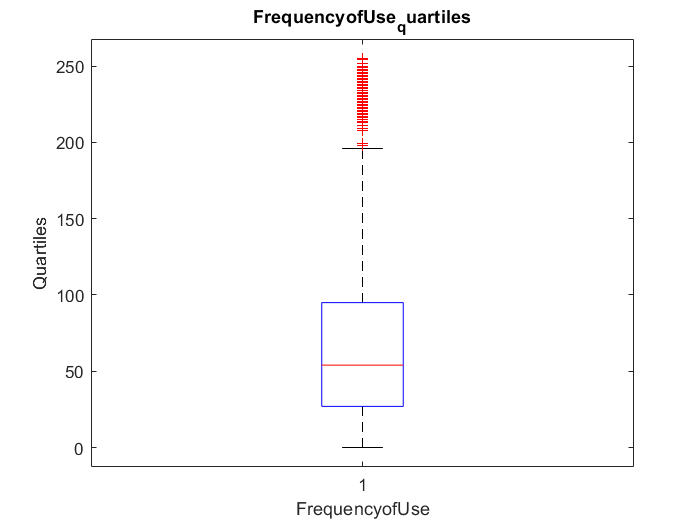


% Boxplot - FrequencyofUse_quartiles
figure(5);
boxplot(FrequencyofUse)
xlabel('FrequencyofUse')
ylabel('Quartiles')
title('FrequencyofUse_quartiles')

8) FrequencyofSMS

FrequencyofSMS_mean        = mean(FrequencyofSMS);
FrequencyofSMS_median      = median(FrequencyofSMS);
FrequencyofSMS_mode        = mode(FrequencyofSMS);
FrequencyofSMS_minimum     = min(FrequencyofSMS);
FrequencyofSMS_maximum     = max(FrequencyofSMS);
FrequencyofSMS_quartiles   = [0.25:0.25:1; quantile(FrequencyofSMS, 0.25:0.25:1)];


% Cell array for FrequencyofSMS stats
FrequencyofSMS_stats = {'Mean', FrequencyofSMS_mean; ...
         'Median', FrequencyofSMS_median; ...
         'Mode', FrequencyofSMS_mode; ...
         'Minimum', FrequencyofSMS_minimum; ...
         'Maximum', FrequencyofSMS_maximum; ...
         'Quartiles', FrequencyofSMS_quartiles}

FrequencyofSMS_stats = 6×2 cell array
    {'Mean'     }    {[ 73.1749]}
    {'Median'   }    {[      21]}
    {'Mode'     }    {[       0]}
    {'Minimum'  }    {[       0]}
    {'Maximum'  }    {[     522]}
    {'Quartiles'}    {2×4 double}


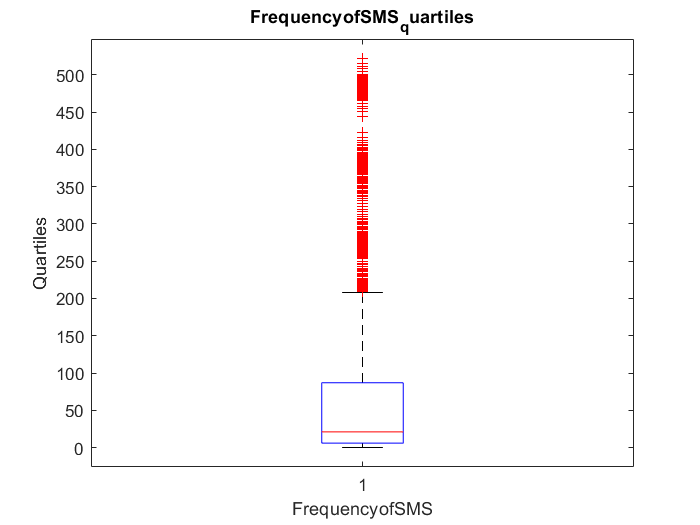


% Boxplot - FrequencyofSMS_quartiles
figure(6);
boxplot(FrequencyofSMS)
xlabel('FrequencyofSMS')
ylabel('Quartiles')
title('FrequencyofSMS_quartiles')

9) DistinctCalledNumbers

DistinctCalledNumbers_mean        = mean(DistinctCalledNumbers);
DistinctCalledNumbers_median      = median(DistinctCalledNumbers);
DistinctCalledNumbers_mode        = mode(DistinctCalledNumbers);
DistinctCalledNumbers_minimum     = min(DistinctCalledNumbers);
DistinctCalledNumbers_maximum     = max(DistinctCalledNumbers);
DistinctCalledNumbers_quartiles   = [0.25:0.25:1; quantile(DistinctCalledNumbers, 0.25:0.25:1)];


% Cell array for DistinctCalledNumbers stats
DistinctCalledNumbers_stats = {'Mean', DistinctCalledNumbers_mean; ...
         'Median', DistinctCalledNumbers_median; ...
         'Mode', DistinctCalledNumbers_mode; ...
         'Minimum', DistinctCalledNumbers_minimum; ...
         'Maximum', DistinctCalledNumbers_maximum; ...
         'Quartiles', DistinctCalledNumbers_quartiles}

DistinctCalledNumbers_stats = 6×2 cell array
    {'Mean'     }    {[ 23.5098]}
    {'Median'   }    {[      21]}
    {'Mode'     }    {[       0]}
    {'Minimum'  }    {[       0]}
    {'Maximum'  }    {[      97]}
    {'Quartiles'}    {2×4 double}


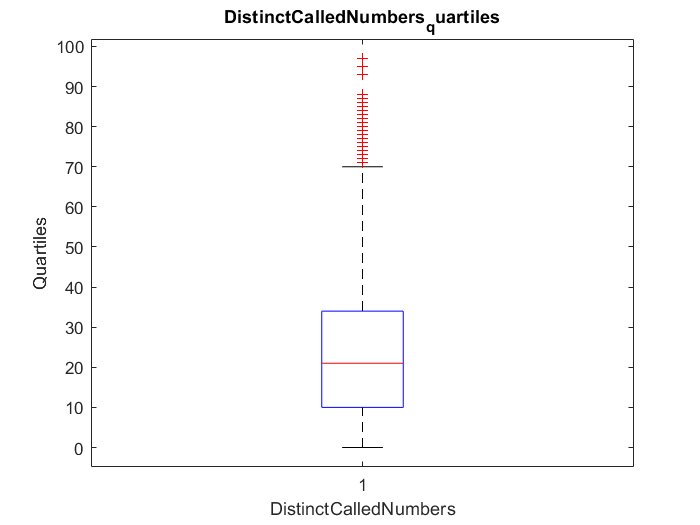


% Boxplot - DistinctCalledNumbers_quartiles
figure(7);
boxplot(DistinctCalledNumbers)
xlabel('DistinctCalledNumbers')
ylabel('Quartiles')
title('DistinctCalledNumbers_quartiles')

14) CustomerValue

CustomerValue_mean        = mean(CustomerValue);
CustomerValue_median      = median(CustomerValue);
CustomerValue_mode        = mode(CustomerValue);
CustomerValue_minimum     = min(CustomerValue);
CustomerValue_maximum     = max(CustomerValue);
CustomerValue_quartiles   = [0.25:0.25:1; quantile(CustomerValue, 0.25:0.25:1)];


% Cell array for CustomerValue stats
CustomerValue_stats = {'Mean', CustomerValue_mean; ...
         'Median', CustomerValue_median; ...
         'Mode', CustomerValue_mode; ...
         'Minimum', CustomerValue_minimum; ...
         'Maximum', CustomerValue_maximum; ...
         'Quartiles', CustomerValue_quartiles}

CustomerValue_stats = 6×2 cell array
    {'Mean'     }    {[170.9503]}
    {'Median'   }    {[120.6750]}
    {'Mode'     }    {[       0]}
    {'Minimum'  }    {[       0]}
    {'Maximum'  }    {[817.6500]}
    {'Quartiles'}    {2×4 double}


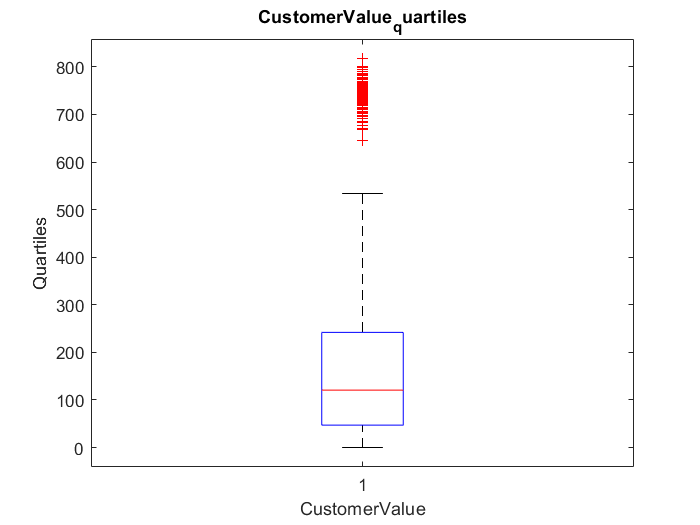


% Boxplot - CustomerValue_quartiles
figure(8);
boxplot(CustomerValue)
xlabel('CustomerValue')
ylabel('Quartiles')
title('CustomerValue_quartiles')

Std. dev.

CallFailure_std	          = [std(CallFailure)];
SubscriptionLength_std    = [std(SubscriptionLength)];	
ChargeAmount_std          = [std(ChargeAmount)];	
SecondsofUse_std          = [std(SecondsofUse)];
FrequencyofUse_std        = [std(FrequencyofUse)];	
FrequencyofSMS_std        = [std(FrequencyofSMS)];
DistinctCalledNumbers_std = [std(DistinctCalledNumbers)];	
CustomerValue_std         = [std(CustomerValue)];

std_dev_cont   = [CallFailure_std(1), ...
             SubscriptionLength_std(1), ...
             ChargeAmount_std(1), ...
             SecondsofUse_std(1), ...
             FrequencyofUse_std(1), ...
             FrequencyofSMS_std(1), ...
             DistinctCalledNumbers_std(1), ...
             CustomerValue_std(1)];

Skewness and Kurtosis

CallFailure_skew_kur	       = [skewness(CallFailure), kurtosis(CallFailure)];
SubscriptionLength_skew_kur    = [skewness(SubscriptionLength), kurtosis(SubscriptionLength)];	
ChargeAmount_skew_kur          = [skewness(ChargeAmount), kurtosis(ChargeAmount)];	
SecondsofUse_skew_kur          = [skewness(SecondsofUse), kurtosis(SecondsofUse)];
FrequencyofUse_skew_kur        = [skewness(FrequencyofUse), kurtosis(FrequencyofUse)];	
FrequencyofSMS_skew_kur        = [skewness(FrequencyofSMS), kurtosis(FrequencyofSMS)];	
DistinctCalledNumbers_skew_kur = [skewness(DistinctCalledNumbers), kurtosis(DistinctCalledNumbers)];
CustomerValue_skew_kur         = [skewness(CustomerValue), kurtosis(CustomerValue)];

skew_cont = [CallFailure_skew_kur(1), SubscriptionLength_skew_kur(1), ...
        ChargeAmount_skew_kur(1), SecondsofUse_skew_kur(1), FrequencyofUse_skew_kur(1), ...
        FrequencyofSMS_skew_kur(1), DistinctCalledNumbers_skew_kur(1), CustomerValue_skew_kur(1)];
kurt_cont = [CallFailure_skew_kur(2), SubscriptionLength_skew_kur(2), ...
        ChargeAmount_skew_kur(2), SecondsofUse_skew_kur(2), FrequencyofUse_skew_kur(2), ...
        FrequencyofSMS_skew_kur(2), DistinctCalledNumbers_skew_kur(2), CustomerValue_skew_kur(2)];

Plotting distribution

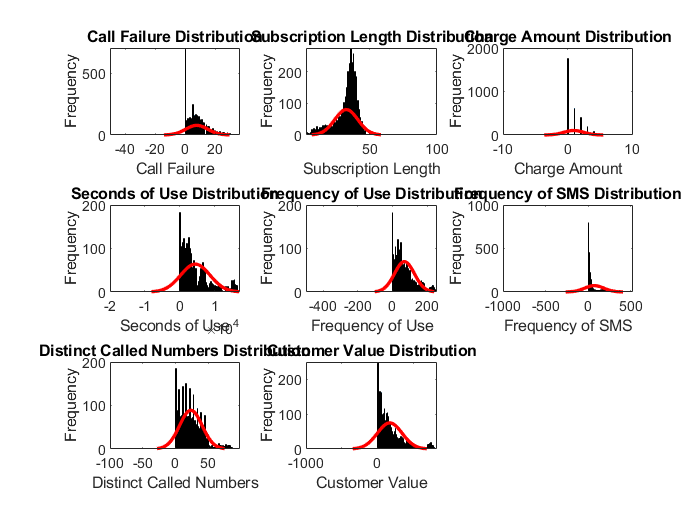

figure(9)

% Call Failure	         
subplot(3,3,1)
histfit(CallFailure, 80)
xlabel('Call Failure')
ylabel('Frequency' )
title('Call Failure Distribution')

% Subscription Length	
subplot(3,3,2)
histfit(SubscriptionLength, 80)
xlabel('Subscription Length')
ylabel('Frequency' )
title('Subscription Length Distribution')

% Charge Amount	
subplot(3,3,3)
histfit(ChargeAmount, 80)
xlabel('Charge Amount')
ylabel('Frequency' )
title('Charge Amount Distribution')

% Seconds of Use
subplot(3,3,4)
histfit(SecondsofUse, 80)
xlabel('Seconds of Use')
ylabel('Frequency' )
title('Seconds of Use Distribution')

% Frequency of Use
subplot(3,3,5)
histfit(FrequencyofUse, 80)
xlabel('Frequency of Use')
ylabel('Frequency' )
title('Frequency of Use Distribution')

% Frequency of SMS
subplot(3,3,6)
histfit(FrequencyofSMS, 80)
xlabel('Frequency of SMS')
ylabel('Frequency' )
title('Frequency of SMS Distribution')

% Distinct Called Numbers
subplot(3,3,7)
histfit(DistinctCalledNumbers, 80)
xlabel('Distinct Called Numbers')
ylabel('Frequency' )
title('Distinct Called Numbers Distribution')

% Customer Value
subplot(3,3,8)
histfit(CustomerValue, 80)
xlabel('Customer Value')
ylabel('Frequency' ) 
title('Customer Value Distribution')

### Correlation plot of cotinuous variables 

- *Please, ****DO NOT**** integrate this section with the previous section!*

- *For some reason, if done, the correlation plot appears inside the distributions plot.*

- *Also figure number for corrplot "figure(500)" is a huge number ****on purpose*** *cause earlier it was mixing with the distribution plots. *

- *Otherwise, you can follow the continuous figure numbers after ****"figure (11)".**** Thanks and apologies for any inconvenience.*

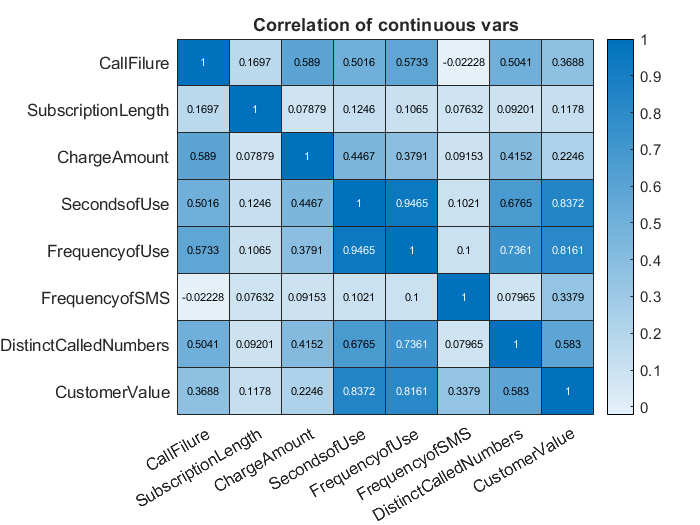

figure(500)
cont_var = [CallFailure, SubscriptionLength, ChargeAmount, SecondsofUse, ...
            FrequencyofUse, FrequencyofSMS, DistinctCalledNumbers, CustomerValue];
h1 = heatmap(corrcoef(cont_var));
labels = ["CallFilure", "SubscriptionLength", "ChargeAmount", "SecondsofUse", ...
          "FrequencyofUse", "FrequencyofSMS", "DistinctCalledNumbers", "CustomerValue"];
h1.XDisplayLabels = labels;
h1.YDisplayLabels = labels; 
title('Correlation of continuous vars')

### Descriptive Statistics | categorical variables

#### Frequency distributions

% Converting complains, AgeGroup, TariffPlan, Status, and Churn into categorical vars.
Complains_Freq_dist  = tabulate(churn_data.Complains);
AgeGroup_Freq_dist   = tabulate(churn_data.AgeGroup);
TariffPlan_Freq_dist = tabulate(churn_data.TariffPlan);
Status_Freq_dist     = tabulate(churn_data.Status);
Churn_Freq_dist      = tabulate(churn_data.Churn);

Std. dev.

Complains_std     	      = [std(churn_data.Complains)]; 
AgeGroup_std              = [std(churn_data.AgeGroup)];	
TariffPlan_std            = [std(churn_data.TariffPlan)];	
Status_std                = [std(churn_data.Status)];	
Churn_std                 = [std(churn_data.Churn)];

std_dev_cat   = [Complains_std(1), ...
             AgeGroup_std(1), ...
             TariffPlan_std(1), ...
             Status_std(1), ...
             Churn_std(1)];

Plotting frequency distribution

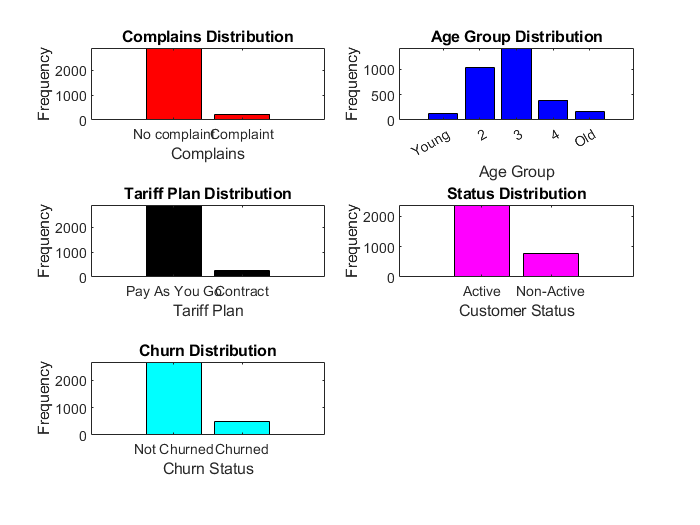

figure(11)

% Complains
subplot(3,2,1)
bar(Complains_Freq_dist(:,1), Complains_Freq_dist(:,2), 'red')
xticklabels({'No complaint', 'Complaint'})
xlabel('Complains')
ylabel('Frequency')
title('Complains Distribution')

% Age Group
subplot(3,2,2)
bar(AgeGroup_Freq_dist(:,1), AgeGroup_Freq_dist(:,2), 'blue')
xticklabels({'Young', '2', '3', '4', 'Old'})
xlabel('Age Group')
ylabel('Frequency')
title('Age Group Distribution')

% Traffic Plan
subplot(3,2,3)
bar(TariffPlan_Freq_dist(:,1), TariffPlan_Freq_dist(:,2), 'black')
xticklabels({'Pay As You Go', 'Contract'})
xlabel('Tariff Plan')
ylabel('Frequency')
title('Tariff Plan Distribution') 

% Status
subplot(3,2,4)
bar(Status_Freq_dist(:,1), Status_Freq_dist(:,2), 'magenta')
xticklabels({'Active', 'Non-Active'})
xlabel('Customer Status')
ylabel('Frequency')
title('Status Distribution')

% Churn
subplot(3,2,5)
bar(Churn_Freq_dist(:,1), Churn_Freq_dist(:,2), 'cyan')
xticklabels({'Not Churned', 'Churned'})
xlabel('Churn Status')
ylabel('Frequency')
title('Churn Distribution')

## **Step 2: Clustering analysis**


% Extract the required variables for analysis part
CallFailure = churn_data.CallFailure;
Complains = churn_data.Complains;
SubscriptionLength = churn_data.SubscriptionLength;
ChargeAmount = churn_data.ChargeAmount;
SecondsOfUse = churn_data.SecondsOfUse;
FrequencyOfUse = churn_data.FrequencyOfUse;
FrequencyOfSMS = churn_data.FrequencyOfSMS;
DistinctCalledNumbers = churn_data.DistinctCalledNumbers;
AgeGroup = churn_data.AgeGroup;
TariffPlan = churn_data.TariffPlan;
Status = churn_data.Status;
Churn = churn_data.Churn;
CustomerValue = churn_data.CustomerValue;


Now, we do the clustering part,

% Select the variables for clustering the dataset 
clustering_vars = [CallFailure, SubscriptionLength, ChargeAmount, SecondsOfUse, FrequencyOfUse, FrequencyOfSMS, DistinctCalledNumbers, CustomerValue];

% Normalize the variables before doing clustering
normalized_vars = zscore(clustering_vars);

% Determination of optimal number of clusters 
E = evalclusters(clustering_vars,'kmeans','silhouette','klist',[2:6])

E =   SilhouetteEvaluation with properties:

    NumObservations: 3150
         InspectedK: [2 3 4 5 6]
    CriterionValues: [0.8455 0.8039 0.7422 0.7696 0.7549]
           OptimalK: 2


kbest = E.OptimalK

kbest = 2

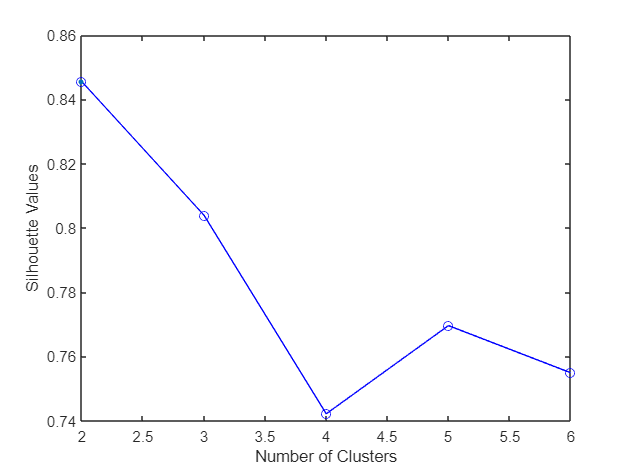

figure;
plot(E)

% Perform k-means clustering
[idx, centroids] = kmeans(normalized_vars, kbest);


% Assign cluster labels to the data to identify the cluster group
clustered_data = [churn_data, table(idx, 'VariableNames', {'Cluster'})]

clustered_data = 3150×15 table
    AnonymousCustomerID    CallFailure    Complains    SubscriptionLength    ChargeAmount    SecondsOfUse    FrequencyOfUse    FrequencyOfSMS    DistinctCalledNumbers    AgeGroup    TariffPlan    Status    Churn    CustomerValue    Cluster
    ___________________    ___________    _________    __________________    ____________    ____________    ______________    ______________    _____________________    ________    __________    ______    _____    _____________    

% Display the clustered data result 
disp(clustered_data);

    AnonymousCustomerID    CallFailure    Complains    SubscriptionLength    ChargeAmount    SecondsOfUse    FrequencyOfUse    FrequencyOfSMS    DistinctCalledNumbers    AgeGroup    TariffPlan    Status    Churn    CustomerValue    Cluster
    ___________________    ___________    _________    __________________    ____________    ____________    ______________    ______________    _____________________    ________    __________    ______    _____    _____________    _______

         

 Now the reporting part here,

% Count the number of customers in each cluster
[cluster_ids, ~, cluster_counts] = unique(idx);
cluster_counts = accumarray(cluster_counts, 1);
disp(cluster_counts);

        2302
         848



% Calculate mean and standard deviation for each cluster
data = clustered_data(:, 2:end-1);
data = table2array(data);
cluster = clustered_data.Cluster;

% Calculate descriptive statistics for each cluster
[mean_Data, std_Data] = grpstats(data, cluster, {'mean', 'std'});

% Display the statistics
for i = 1:size(mean_Data, 1)
    fprintf('Cluster %d:\n', i);
    for j = 1:size(data, 2)
        fprintf('Variable %d:\n', j);
        fprintf('Mean: %.2f\n', mean_Data(i, j));
        fprintf('Standard Deviation: %.2f\n\n', std_Data(i, j));
    end
end

Cluster 1:


Variable 1:


Mean: 5.51


Standard Deviation: 5.60



Variable 2:


Mean: 0.09


Standard Deviation: 0.29



Variable 3:


Mean: 32.07


Standard Deviation: 8.61



Variable 4:


Mean: 0.50


Standard Deviation: 0.87



Variable 5:


Mean: 2411.23


Standard Deviation: 1769.13



Variable 6:


Mean: 41.64


Standard Deviation: 27.80



Variable 7:


Mean: 60.57


Standard Deviation: 108.78



Variable 8:


Mean: 16.81


Standard Deviation: 13.04



Variable 9:


Mean: 2.83


Standard Deviation: 0.85



Variable 10:


Mean: 1.03


Standard Deviation: 0.18



Variable 11:


Mean: 1.34


Standard Deviation: 0.47



Variable 12:


Mean: 0.21


Standard Deviation: 0.41



Variable 13:


Mean: 98.08


Standard Deviation: 79.15



Cluster 2:


Variable 1:


Mean: 13.38


Standard Deviation: 8.10



Variable 2:


Mean: 0.03


Standard Deviation: 0.17



Variable 3:


Mean: 33.83


Standard Deviation: 8.35



Variable 4:


Mean: 2.14


Standard Deviation: 2.14



Variable 5:


Mean: 10067.92


Standard Deviation: 3757.83



Variable 6:


Mean: 144.99


Standard Deviation: 48.38



Variable 7:


Mean: 107.40


Standard Deviation: 114.38



Variable 8:


Mean: 41.70


Standard Deviation: 13.67



Variable 9:


Mean: 2.82


Standard Deviation: 0.99



Variable 10:


Mean: 1.20


Standard Deviation: 0.40



Variable 11:


Mean: 1.00


Standard Deviation: 0.00



Variable 12:


Mean: 0.01


Standard Deviation: 0.10



Variable 13:


Mean: 368.76


Standard Deviation: 200.41



figure(12)
churn = clustered_data.Churn;
cluster = clustered_data.Cluster;
% Count occurrences of churn within each cluster
unique_Clusters = unique(cluster);

unique_Clusters =      1
     2


unique_Churn = unique(churn);

unique_Churn =      0
     1


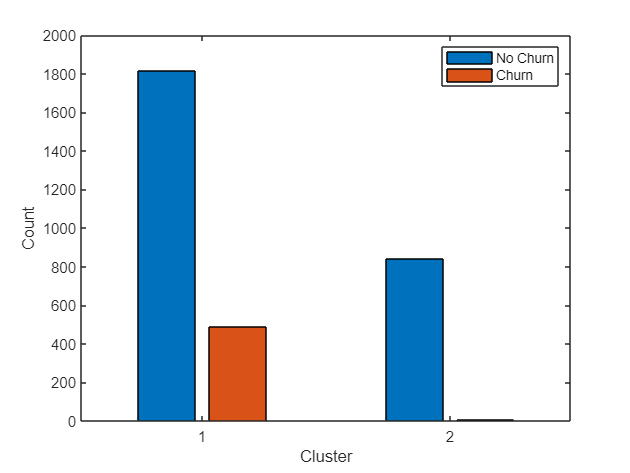

churnCounts = zeros(numel(unique_Clusters), numel(unique_Churn));

for i = 1:numel(unique_Clusters)
    for j = 1:numel(unique_Churn)
        churnCounts(i, j) = sum(cluster == unique_Clusters(i) & churn == unique_Churn(j));
    end
end
% Bar plot
bar(churnCounts, 'grouped');
xlabel('Cluster');
ylabel('Count');
legend("No Churn", "Churn")

Step 3: Model Development

- Normalizing the dataset

- Splitting data into Training, Testing and Validation data

- Creating Lasso Logistic Regression and SVM and Classification tree.

- Evaluation of the classification model.

% Set the random number generator to its default state
rng('default');

% Creating Vectors for target Variable
Y = churn_data.Churn;
X = churn_data{:,{'AgeGroup', 'CallFailure', 'ChargeAmount', 'Complains',...
    'CustomerValue', 'DistinctCalledNumbers', 'FrequencyOfSMS', 'FrequencyOfUse',...
    'SecondsOfUse', 'SubscriptionLength', 'Status', 'TariffPlan'}};

% Normalize the features using z-score normalization
X_norm = zscore(X);

% Splitting the dataset in Training and Testing Data
n = length(Y);
c = cvpartition(n,"holdout",0.3);
Xtrain = X_norm(training(c),:);
Xtest = X_norm(test(c),:);
Ytrain = Y(training(c),:);
Ytest = Y(test(c),:);

% Splitting the training data into training and validation data using cross validation
n2 = length(Ytrain);
cv2 = cvpartition(n2,'KFold', 4);

% Logistic regression Model
glm1 = fitglm(Xtrain,Ytrain)

glm1 = Generalized linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12
    Distribution = Normal

Estimated Coefficients:
                    Estimate        SE         tStat       pValue   
                   __________    _________    _______    ___________

    (Intercept)       0.15405    0.0056833     27.106    8.6573e-140
    x1              -0.011495    0.0088655    -1.2966        0.19492
    x2               0.048868    0.0096141      5.083     4.0302e-07
    x3              -0.025992     0.010177    -2.5541       0.010713
    x4                0.14898    0.0060053     24.809    5.8568e-120
    x5               0.013646     0.018828    0.72475        0.46868
    x6              -0.0

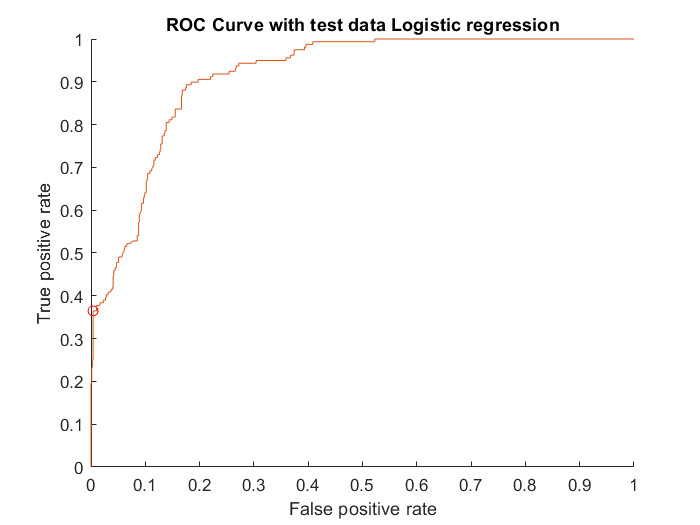

ptest1 =predict(glm1,Xtest);
[xxLR,yyLR,Tresholds_LR,auctest_LR, OPTROCPT1] = perfcurve(Ytest,ptest1,'1');
figure;
hold on
plot(OPTROCPT1(1),OPTROCPT1(2),'ro')
plot(xxLR,yyLR)
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curve with test data Logistic regression')
hold off

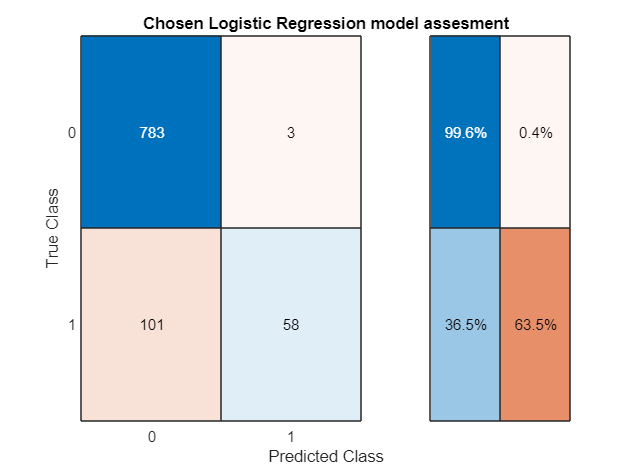

ThresholdForLR = Tresholds_LR((xxLR==OPTROCPT1(1))&(yyLR==OPTROCPT1(2)));
ptest1Binom = double(ptest1>=ThresholdForLR);

% Logistic Regression
confusion_matrix_LR = confusionchart(Ytest, ptest1Binom,'RowSummary','row-normalized');
title("Chosen Logistic Regression model assesment")

TN_LR = 783; FP_LR = 3; TP_LR = 58; FN_LR = 101; Total = 945;


%Compute accuracy
accuracy_LR= (TP_LR + TN_LR)/Total

accuracy_LR = 0.8899


% Compute precision, recall, and F1 score
precision_LR = TP_LR / (TP_LR + FP_LR)

precision_LR = 0.9508

recall_LR = TP_LR / (TP_LR + FN_LR)

recall_LR = 0.3648

F1score_LR = 2 * precision_LR * recall_LR / (precision_LR + recall_LR)

F1score_LR = 0.5273


% Training lasso logistic regression models
[B4,FitInfo4] = lassoglm(Xtrain,Ytrain,'binomial','CV',cv2);

% Number of Features 
idxIndex1SE = FitInfo4.Index1SE;
Number_of_predictors_lamnda1SE = FitInfo4.DF(idxIndex1SE);
idxIndexMinDev = FitInfo4.IndexMinDeviance;
Number_of_predictors_lamndaMinDev = FitInfo4.DF(idxIndexMinDev);
fprintf("If you use LambdaMinDev, we will have %d features"...
    + newline + "If you use  Lambda1SE, we will have %d features", Number_of_predictors_lamndaMinDev, Number_of_predictors_lamnda1SE);

If you use LambdaMinDev, we will have 11 features
If you use  Lambda1SE, we will have 11 features

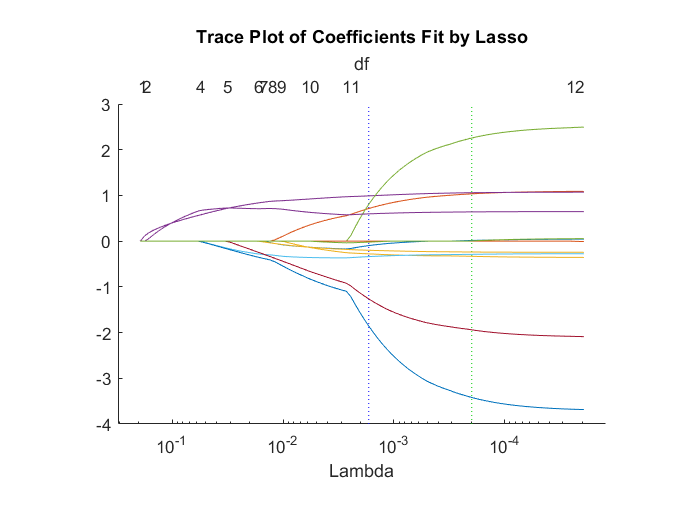

% Plotting the lasso plots
lassoPlot(B4,FitInfo4,'PlotType','Lambda','XScale','log');

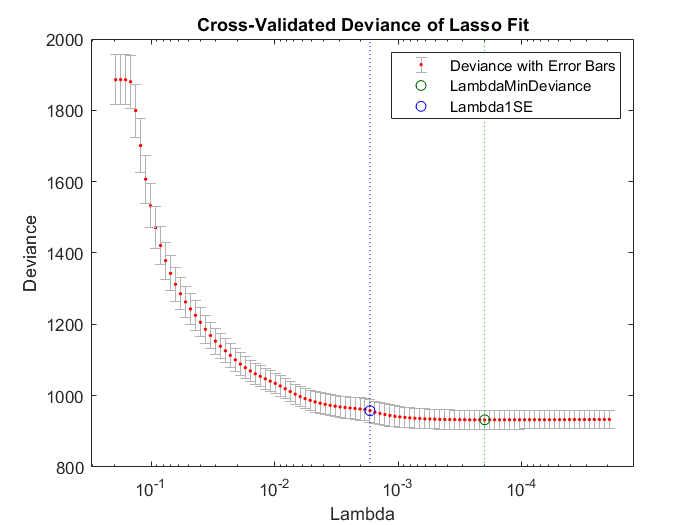

lassoPlot(B4,FitInfo4,'plottype','CV'); 
legend('show')

% Retraining the Model
optimal_lambda = FitInfo4.Lambda1SE;
[Bfinal_Lamnda1SE,fitInfofinal_Lamnda1SE] = lassoglm(Xtrain,Ytrain,'binomial','Lambda',optimal_lambda);
B0_final1SE= fitInfofinal_Lamnda1SE.Intercept;
coef_final_Lamnda1SE = [B0_final1SE; Bfinal_Lamnda1SE];
test_predictions_lasso_Lamnda1SE = glmval(coef_final_Lamnda1SE,Xtest,'logit');

% Training SVM model
svm1 = fitcsvm(Xtrain,Ytrain,'KernelFunction','RBF','KernelScale','auto', 'CVPartition', cv2);
svm2 = fitcsvm(Xtrain,Ytrain,'KernelFunction','polynomial', 'CVPartition', cv2);
svm3 = fitcsvm(Xtrain,Ytrain,'KernelFunction','linear', 'CVPartition', cv2);
% Accuracy of models
cross_validation_error_svm1 = kfoldLoss(svm1);
cross_validation_accuracy_svm1 = 1 - cross_validation_error_svm1 

cross_validation_accuracy_svm1 = 0.9451

cross_validation_error_svm2 = kfoldLoss(svm2);
cross_validation_accuracy_svm2 = 1- cross_validation_error_svm2

cross_validation_accuracy_svm2 = 0.9587

cross_validation_error_svm3 = kfoldLoss(svm3);
cross_validation_accuracy_svm3 = 1- cross_validation_error_svm3

cross_validation_accuracy_svm3 = 0.8989


% Final SVM model
disp("The cross-validation accuracy in model 2 is higher"...
    + newline + "so the final model is created using "...
    + newline + "Polynomial Kernel Function")

The cross-validation accuracy in model 2 is higher
so the final model is created using 
Polynomial Kernel Function



svm_final = fitcsvm(Xtrain,Ytrain,'KernelFunction','Polynomial');

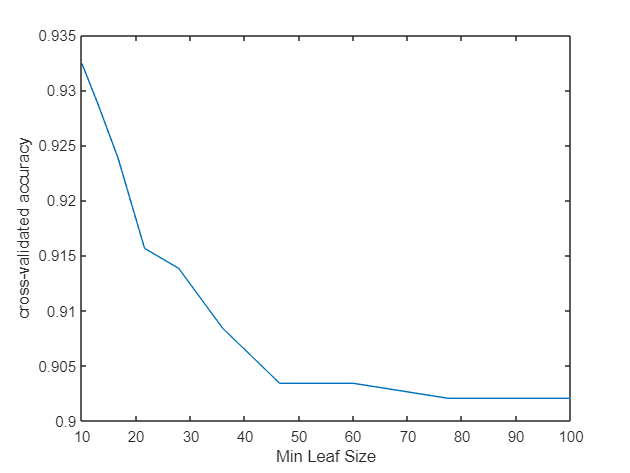

% Training Classification tree model
leafs = logspace(1,2,10);
N = numel(leafs);
accuracy_mdl = zeros(N,1);
for n=1:N
    t = fitctree(Xtrain, Ytrain,'CVPartition', cv2, 'MinLeafSize',leafs(n));
    accuracy_mdl(n) = 1 - kfoldLoss(t);
end
plot(leafs,accuracy_mdl);
xlabel('Min Leaf Size');
ylabel('cross-validated accuracy');

[max_acc, idx] = max(accuracy_mdl);
optimal_min_leaf_size = leafs(idx);
fprintf('Optimal minimum leaf size = %f, with cross-validated accuracy = %f\n', optimal_min_leaf_size, max_acc);

Optimal minimum leaf size = 10.000000, with cross-validated accuracy = 0.932426



final_model_tree =fitctree(Xtrain, Ytrain,'MinLeafSize',optimal_min_leaf_size);

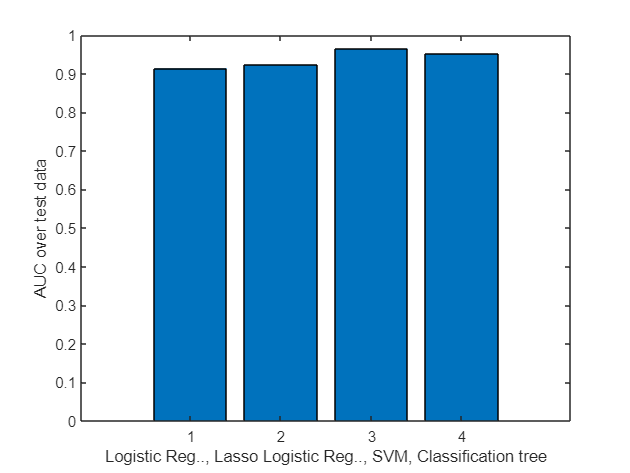

% AUC curve 
% SVM model
ScoreSVMModel = fitPosterior(svm_final);
[predictions_svm,score_svm] = predict(ScoreSVMModel,Xtest);
[Xsvm,Ysvm,Tsvm,AUCsvm] = perfcurve(Ytest,score_svm(:,2),'1');

% Tree model
[predictions_tree,score_tree] = predict(final_model_tree,Xtest);
[Xtree,Ytree,Tree,AUCtree] = perfcurve(Ytest,score_tree(:,2),'1');

% Lasso logistic regression
[xxtest_lasso_Lamnda1SE,yytest_lasso_Lamnda1SE,Tresholds_lasso_Lamnda1SE,auctest_lasso_Lamnda1SE,OPTROCPT_lasso_Lamnda1SE ] = perfcurve(Ytest,test_predictions_lasso_Lamnda1SE,'1');

% AUC for all model
auctest_all=[auctest_LR; auctest_lasso_Lamnda1SE; AUCsvm; AUCtree];
bar (auctest_all)
xlabel('Logistic Reg.., Lasso Logistic Reg.., SVM, Classification tree'); ylabel('AUC over test data');


% Evaluation of model
fprintf("The AUC of Lasso Logistic Regression, SVM, Classification tree are %.4f, %.4f and %.4f respectively" ...
    + newline + "Classification tree and SVM performs better than Lasso Logistic Regression."...
    + newline + "SVM performs slightly better than Classification tree.", auctest_all(1), auctest_all(2), auctest_all(3));

The AUC of Lasso Logistic Regression, SVM, Classification tree are 0.9145, 0.9230 and 0.9652 respectively
Classification tree and SVM performs better than Lasso Logistic Regression.
SVM performs slightly better than Classification tree.

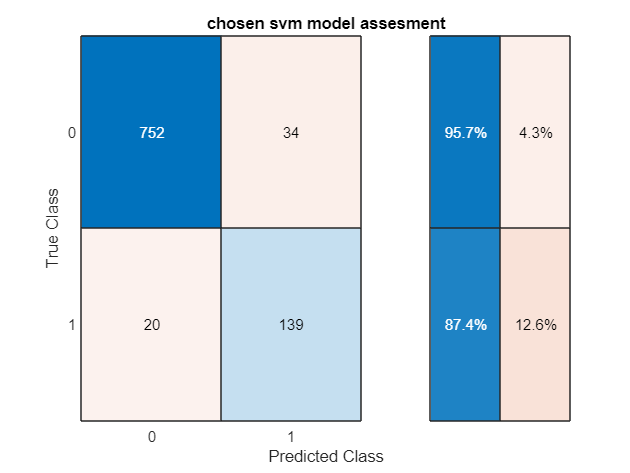

% Confusion matrix and F1 score
% SVM
predicitions_over_test_data_svm = predict(svm_final,Xtest);
confusion_matrix_svm = confusionchart(Ytest,predicitions_over_test_data_svm,'RowSummary','row-normalized');
title("chosen svm model assesment")

TN_svm = 752; FP_svm = 34; TP_svm = 139; FN_svm = 20; Total = 945;
accuracy_svm = (TP_svm + TN_svm)/Total

accuracy_svm = 0.9429

precision_svm = TP_svm/ (TP_svm + FP_svm)

precision_svm = 0.8035

recall_svm = TP_svm / (TP_svm + FN_svm)

recall_svm = 0.8742

F1score_svm = 2 * precision_svm * recall_svm / (precision_svm + recall_svm)

F1score_svm = 0.8373

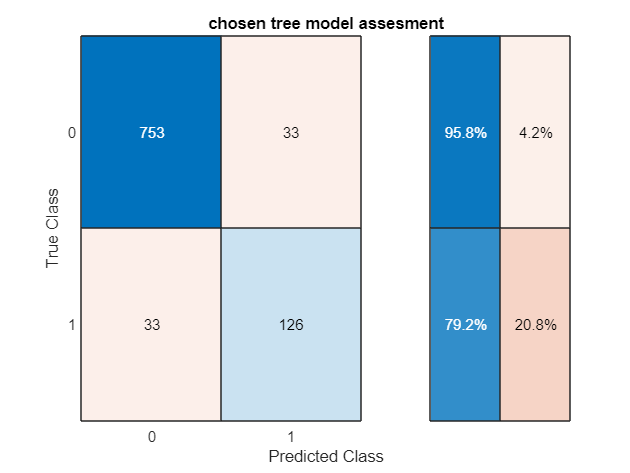

% Tree classification
predicitions_over_test_data_tree= predict(final_model_tree,Xtest);
confusion_matrix_tree = confusionchart(Ytest, predicitions_over_test_data_tree,'RowSummary','row-normalized');
title("chosen tree model assesment")

TN_tree = 753; FP_tree = 33; TP_tree = 126; FN_tree = 33; Total = 945;

% Compute accuracy
accuracy_tree= (TP_tree + TN_tree)/Total

accuracy_tree = 0.9302


% Compute precision, recall, and F1 score
precision_tree = TP_tree / (TP_tree + FP_tree)

precision_tree = 0.7925

recall_tree = TP_tree / (TP_tree + FN_tree)

recall_tree = 0.7925

F1score_tree = 2 * precision_tree * recall_tree / (precision_tree + recall_tree)

F1score_tree = 0.7925

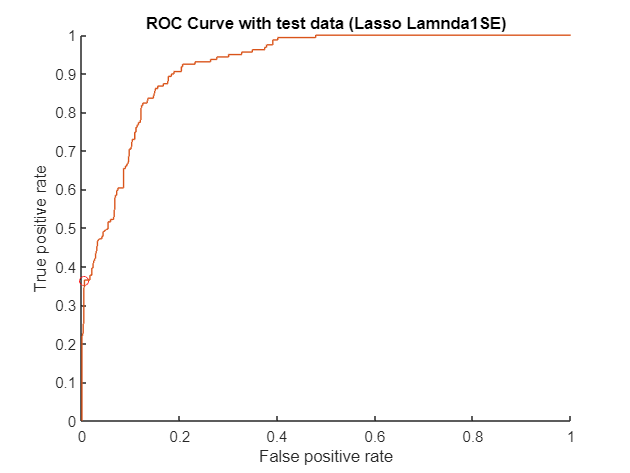

% Lasso Logistic regression
figure;
hold on
plot(OPTROCPT_lasso_Lamnda1SE(1),OPTROCPT_lasso_Lamnda1SE(2),'ro')
plot(xxtest_lasso_Lamnda1SE,yytest_lasso_Lamnda1SE)
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curve with test data (Lasso Lamnda1SE)')
hold off

Threshold_lasso_1SE =Tresholds_lasso_Lamnda1SE((xxtest_lasso_Lamnda1SE==OPTROCPT_lasso_Lamnda1SE(1))&(yytest_lasso_Lamnda1SE==OPTROCPT_lasso_Lamnda1SE(2)))

Threshold_lasso_1SE = 0.6050

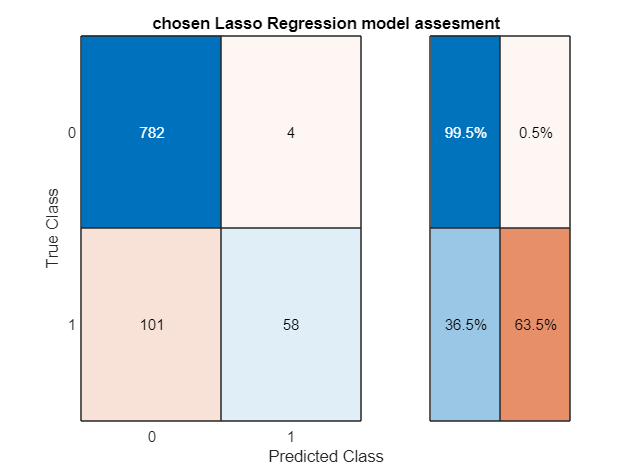

predictions_lasso_regression = double(test_predictions_lasso_Lamnda1SE >= Threshold_lasso_1SE);

confusion_matrix_lasso = confusionchart(Ytest,predictions_lasso_regression ,'RowSummary','row-normalized');
title("chosen Lasso Regression model assesment")

TN_lasso = 782; FP_lasso = 4; TP_lasso = 58; FN_lasso = 101; Total = 945;

%Compute accuracy
accuracy_lasso= (TP_lasso + TN_lasso)/Total

accuracy_lasso = 0.8889


% Compute precision, recall, and F1 score
precision_lasso = TP_lasso / (TP_lasso + FP_lasso)

precision_lasso = 0.9355

recall_lasso = TP_lasso / (TP_lasso + FN_lasso)

recall_lasso = 0.3648

F1score_lasso = 2 * precision_lasso * recall_lasso / (precision_lasso + recall_lasso)

F1score_lasso = 0.5249

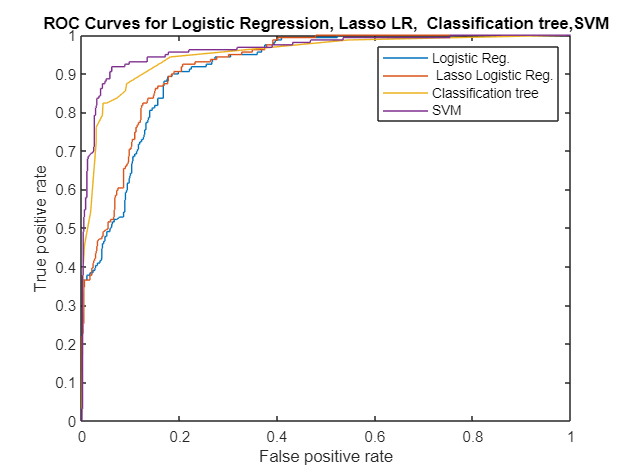

% Visual Evaluation through ROC Plot
plot(xxLR, yyLR)
hold on
plot(xxtest_lasso_Lamnda1SE,yytest_lasso_Lamnda1SE)
hold on
plot(Xtree,Ytree)
hold on
plot(Xsvm,Ysvm)
legend('Logistic Reg.',' Lasso Logistic Reg.','Classification tree', 'SVM')
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curves for Logistic Regression, Lasso LR,  Classification tree,SVM')
hold off

% Evaluation of Models based on F1 score
disp("Based on the F1-scores you provided, the SVM model has the best performance over the test data," ...
    + newline + "followed by the Classification Tree and Lasso Logistic Regression model with Lambda1SE model respectively.")

Based on the F1-scores you provided, the SVM model has the best performance over the test data,
followed by the Classification Tree and Lasso Logistic Regression model with Lambda1SE model respectively.
